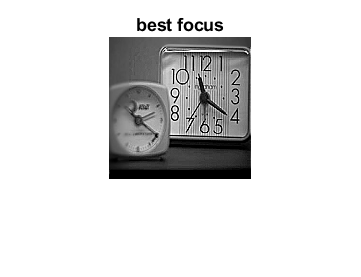

%just change the folder as per your dataset
%change the extension accordingly as well
%make sure line 32 and 33 are commented out in function block
%this code will run
image_folder = 'test_grayscale_images';
filenames = dir(fullfile(image_folder,'*.bmp'));
total_images = numel(filenames);
%%
devmax = 0; devtot = [];
xstart = input('enter region of interest for rows  ');
xend = input('enter region of interest ending for rows  ');
ystart = input('enter region of interest for columns  ');
yend = input('enter region of interest for columns for end  ');
%%
for n=1:total_images
    q = fullfile(image_folder,filenames(n).name);
    I = imread(q);
    filter = fspecial('unsharp');
    outimg = RegionofInterest(I,filter,xstart,xend,ystart,yend);
%     figure(n)
%     imshow(outimg)
    z = std2(outimg);
    devtot(n) = z;
    if z>devmax
        devmax = z;
        resimg = outimg;
    end
end
%%
figure
imshow(resimg)
title('best focus')

%to see the mask uncomment 29 and 30 in the function block 
%to view the mask evaluate this section of the code in the command line
outimg = RegionofInterest(I,filter,xstart,xend,ystart,yend);